close all
clc
path = '/Users/veronicalucchetti/Desktop/TESI/BankClients.mat';

load BankClients.mat

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
% Removing the gender and the family size
%Data(:, "Gender") = [];
%Data(:, "FamilySize") = [];
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]
% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features
% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end-1)]; % To use the dummy variables in a model, we must delete a column
end

X = [XCat XNum];

dati = Data;

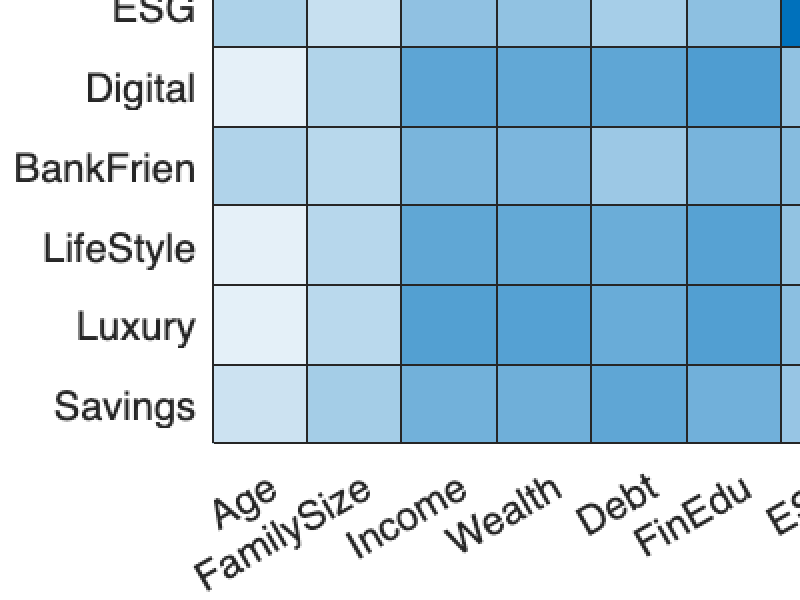

%we can avoid running this part
figure
R = corrcoef(XNum); %computation of the correlation matric
yvalues = {'Age','FamilySize','Income','Wealth','Debt','FinEdu','ESG','Digital','BankFrien','LifeStyle','Luxury','Savings'};
xvalues = {'Age','FamilySize','Income','Wealth','Debt','FinEdu','ESG','Digital','BankFrien','LifeStyle','Luxury','Savings'};
h = heatmap(xvalues,yvalues, R );
h.Title = 'Correlation matrix of numerical features';

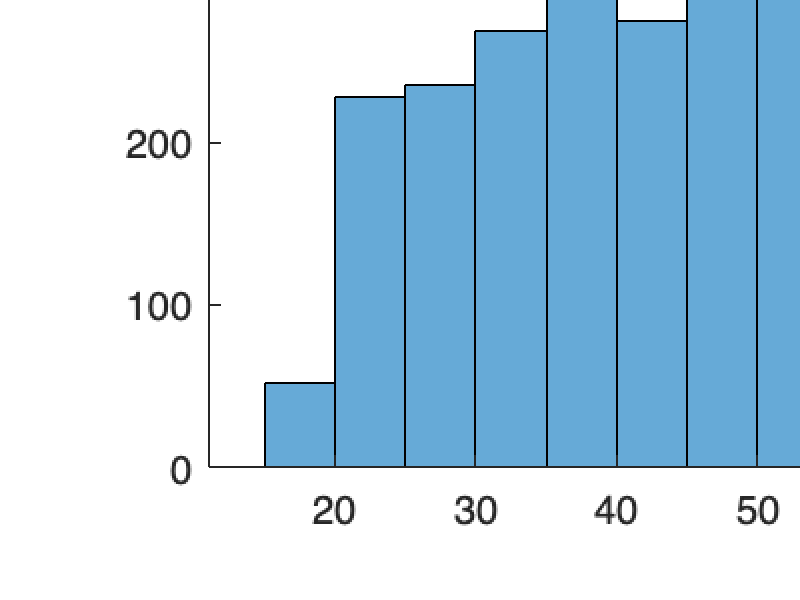

%we can avoid running this part
histogram(Data.Age)
title('Age')

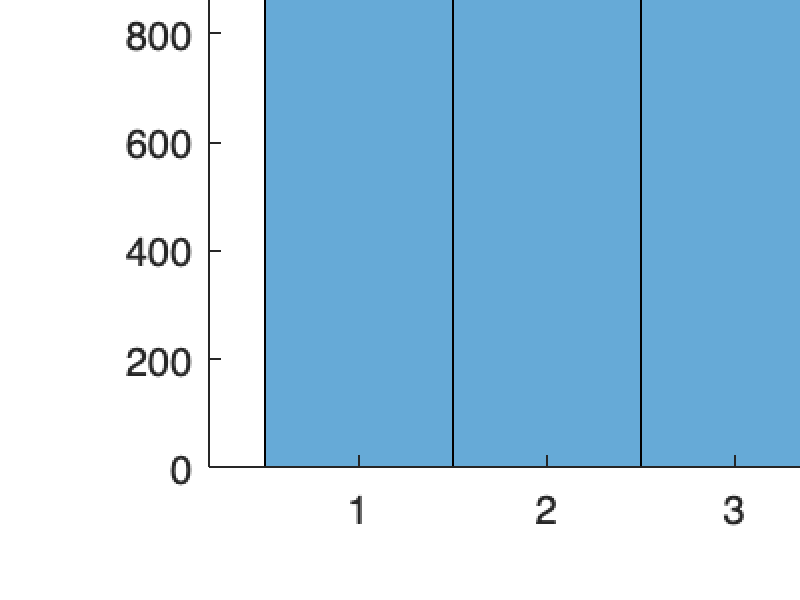


histogram(Data.FamilySize)
title('FamilySize')

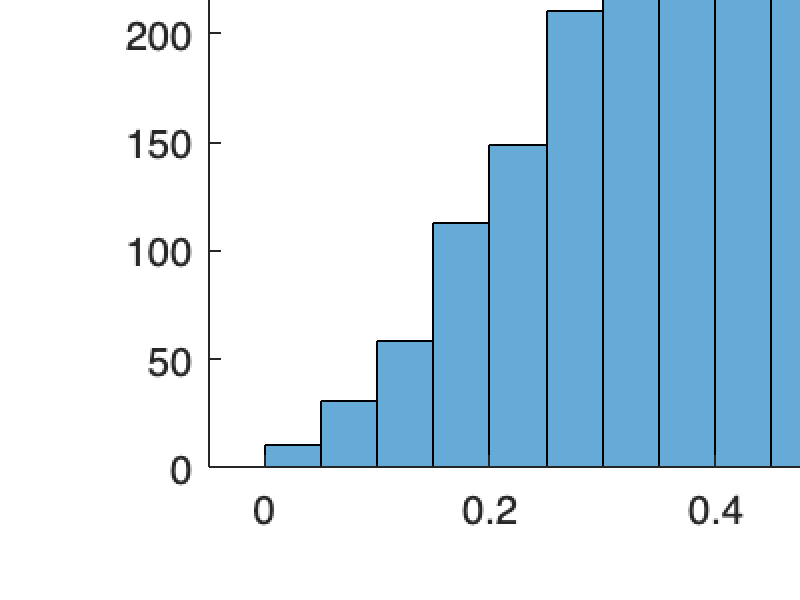


histogram(Data.Income)
title("Income")

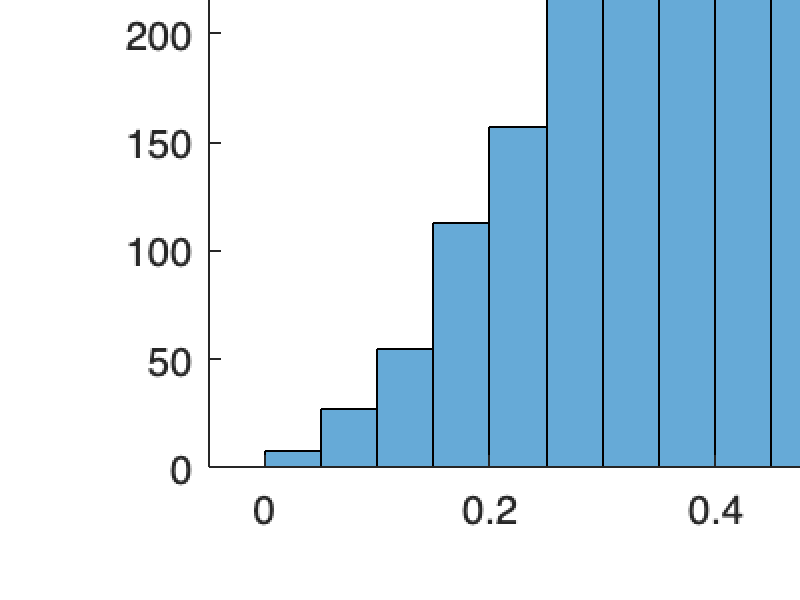


histogram(Data.Wealth)
title("Wealth")

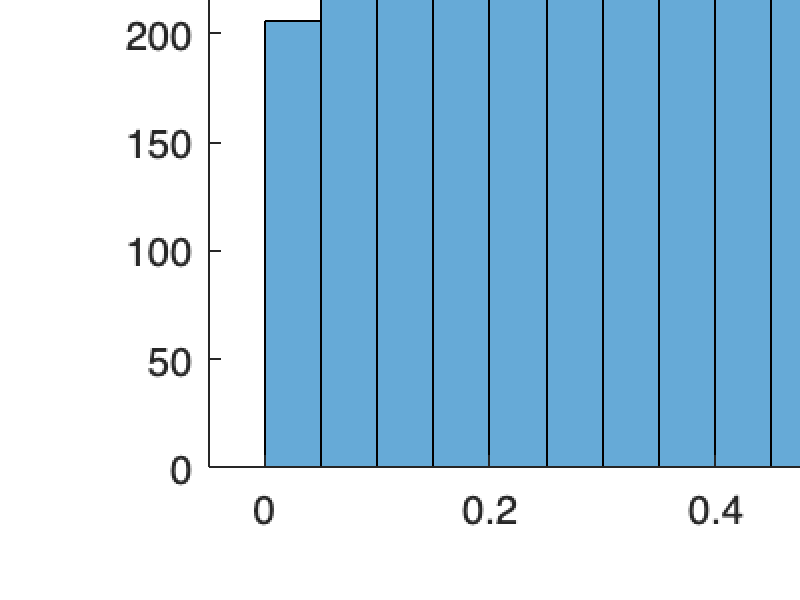


histogram(Data.Debt)
title("Debt")

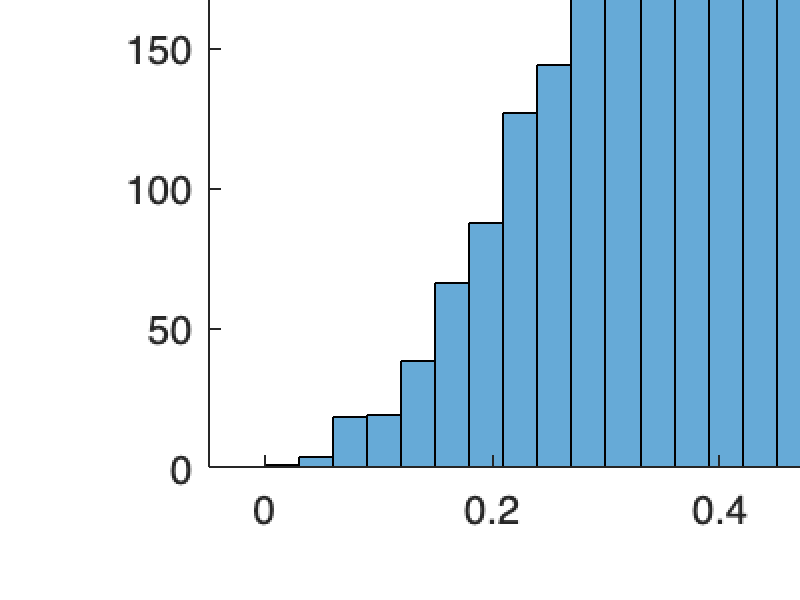


histogram(Data.FinEdu)
title("Financial Education")

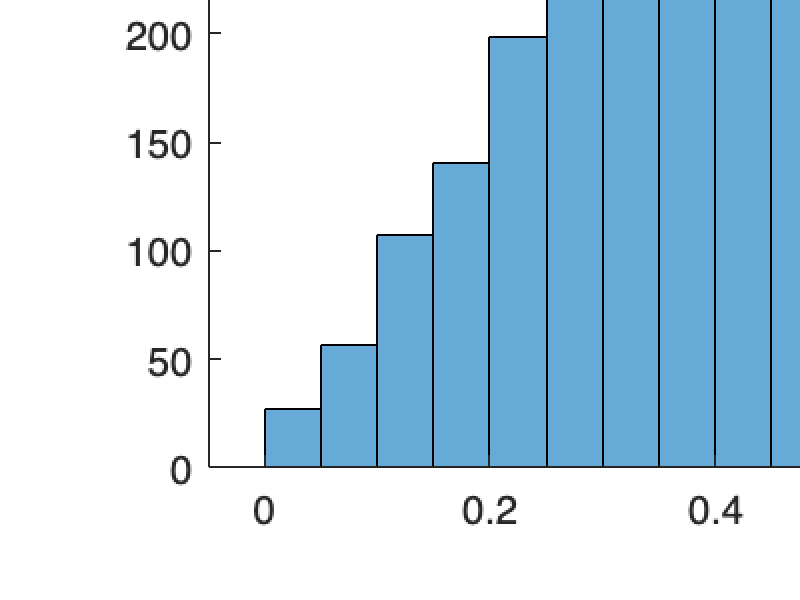


histogram(Data.Digital)
title("Digital Propensity")

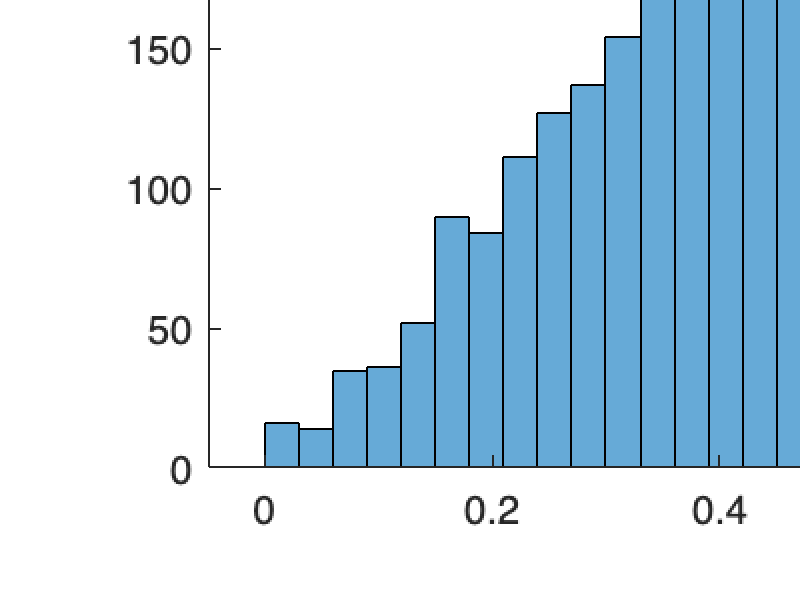


histogram(Data.Saving)
title('Saving Propensity')


tabulate(Data.Investments)

  Value    Count   Percent
      1     1314     26.28%
      2     1496     29.92%
      3     2190     43.80%



tabulate(Data.Job)

  Value    Count   Percent
      1      609     12.18%
      2     3284     65.68%
      3      144      2.88%
      4      107      2.14%
      5      856     17.12%



nSubSample = 1950;
rng('default') % for reproducibility
randRows = randperm(size(X, 1), nSubSample);
X = X(randRows', :);
%Dataset used later for cluster inspection
dati = dati(randRows', :); 


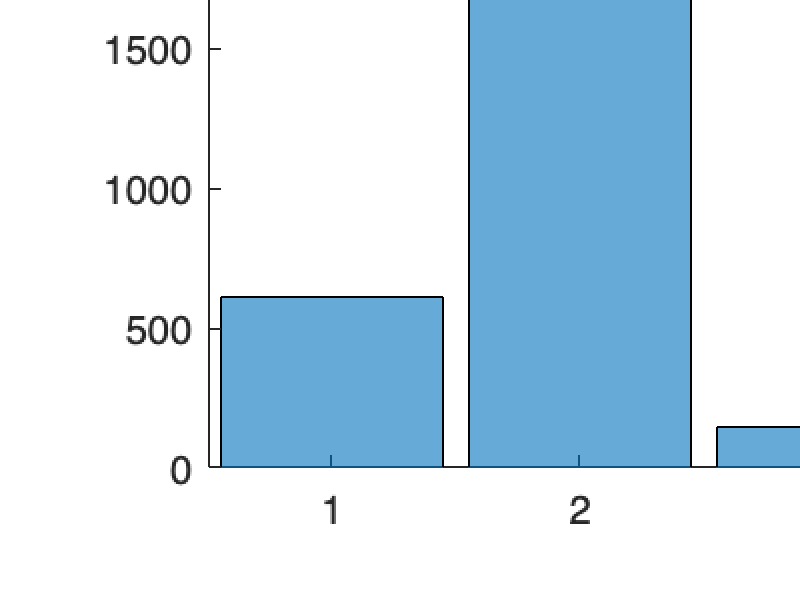

%we can avoid running this part
histogram(CatFeatures.Job)
title('Job type')

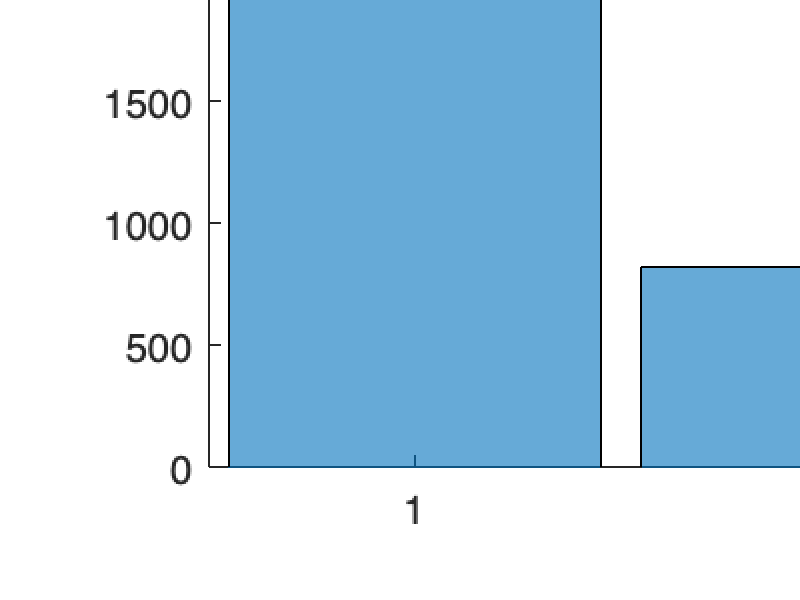


histogram(CatFeatures.Area)
title('Geographical area of residency')

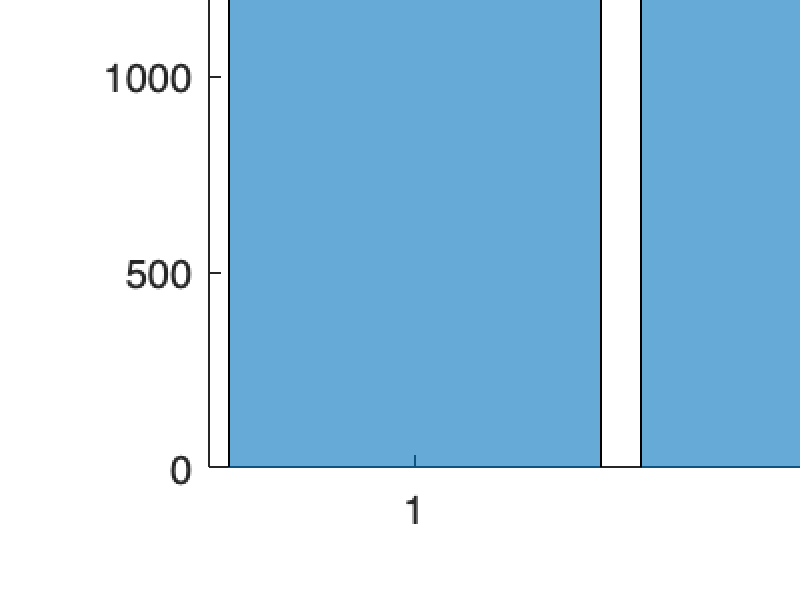


histogram(CatFeatures.CitySize)
title('City size')


histogram(CatFeatures.Investments)
title('Investment propensity')

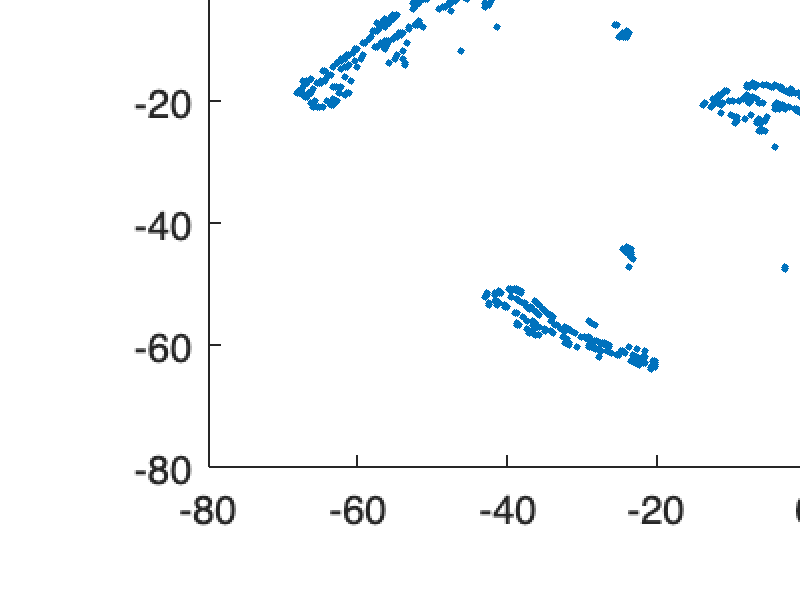

%we can avoid running this part
rng('default') % for reproducibility 9clu
Y = tsne(X,'Algorithm','exact','Distance', @MixDistanceL1);
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Manhattan')

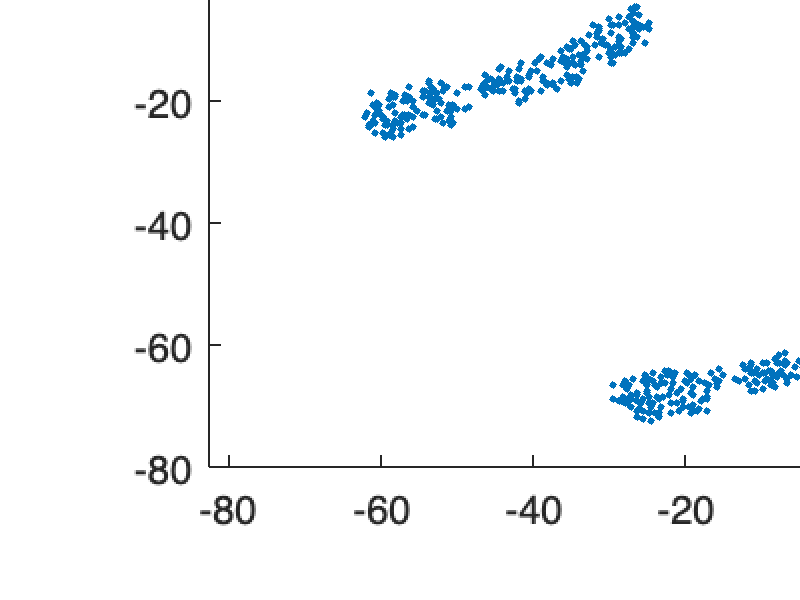

%we can avoid running this part
rng('default') % for reproducibility 9clu
Y = tsne(X,'Algorithm','exact','Distance', @MixDistanceL2);
gscatter(Y(:,1),Y(:,2))
title('Mixed: Hamming + Euclidean')

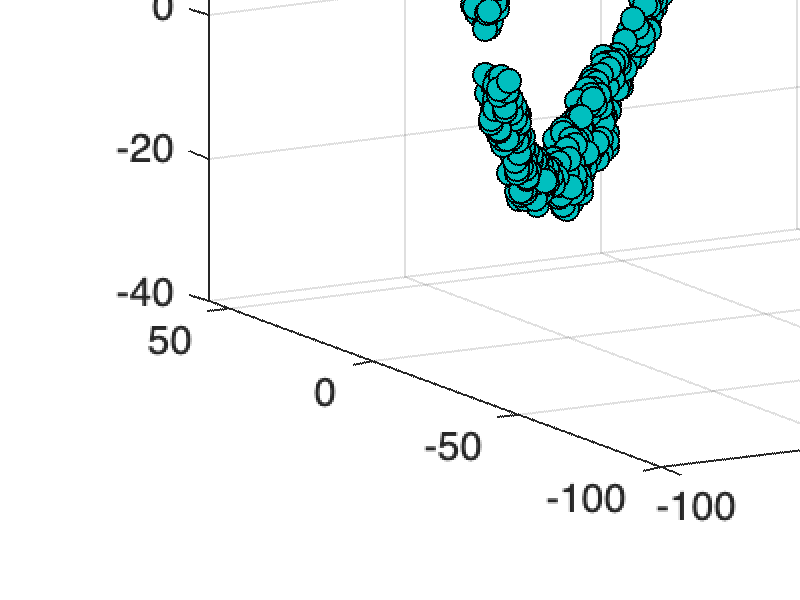

%we can avoid running this part
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @MixDistanceL2,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D EmbeddingHamming+Euclidean')
view(-30,15)

%we can avoid running this part
rng('default') % for fair comparison
Y = tsne(X,'Algorithm','exact','Distance', @MixDistanceL1,'NumDimensions',3);
figure
scatter3(Y(:,1),Y(:,2),Y(:,3),...
        'MarkerEdgeColor','k',...
        'MarkerFaceColor',[0 .75 .75])
title('3-D EmbeddingHamming+Manhattan')
view(-30,15)

D1 = pdist(X, @MixDistanceL1);   
%calculate the distance between every pair of objects in the dataset using MixDistanceL1
D2 = pdist(X, @MixDistanceL2); 
%calculate the distance between every pair of objects in the dataset using MixDistanceL2

%linkages using the L1 mix distance
single1 = linkage(D1, "single");
complete1 = linkage(D1, "complete");
average1 = linkage(D1, "average");
weighted1 = linkage(D1, "weighted");
%linkages using the L2 mix distance
single2 = linkage(D2, "single");
complete2 = linkage(D2, "complete");
average2 = linkage(D2, "average");
weighted2 = linkage(D2, "weighted");

c_single1 = cophenet(single1,D1)

c_single1 = 0.4840


c_single2 = cophenet(single2,D2)

c_single2 = 0.2631


c_average1 = cophenet(average1,D1)

c_average1 = 0.7188


c_average2 = cophenet(average2,D2)   % migliore, 0.8090

c_average2 = 0.7079


c_complete1 = cophenet(complete1,D1)

c_complete1 = 0.6140


c_complete2 = cophenet(complete2,D2)

c_complete2 = 0.7230


c_weighted1 = cophenet(weighted1,D1)

c_weighted1 = 0.6783


c_weighted2 = cophenet(weighted2,D2)

c_weighted2 = 0.7178

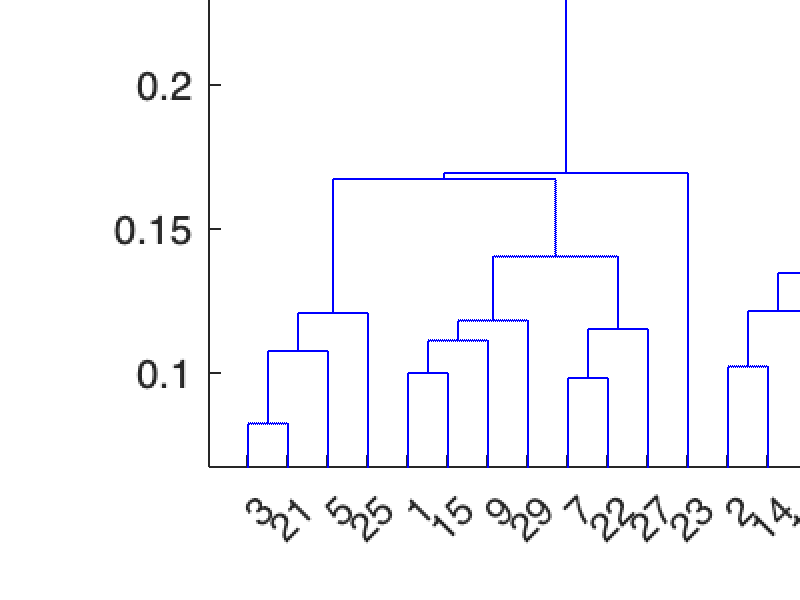

% Complete Dataset used for clustering
X = [XCat XNum];
% Dataset with the original variables used for cluster inspection
dati = Data;

D2 = pdist(X, @MixDistanceL2);
average2 = linkage(D2, "average");

figure
dendrogram(average2)
title("Average Linkage")

T5 = cluster(complete2,'maxclust',5);

T6 = cluster(complete2,'maxclust',6);

T7 = cluster(complete2,'maxclust',7);

T8 = cluster(complete2,'maxclust',8);

T9 = cluster(complete2,'maxclust',9);

clust = [T5 T6 T7 T8 T9];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');

Error using clustering.evaluation.ClusterCriterion
The predictor matrix X and the matrix of clustering solutions must have the same number of rows.

Error in clustering.evaluation.CalinskiHarabaszEvaluation (line 55)
      this = this@clustering.evaluation.ClusterCriterion(X,Y,klist);

Error in 

figure
plot(eva1)

eva1


eva2 = evalclusters(X,clust,'DaviesBouldin');

Error using clustering.evaluation.ClusterCriterion
The predictor matrix X and the matrix of clustering solutions must have the same number of rows.

Error in clustering.evaluation.DaviesBouldinEvaluation (line 55)
      this = this@clustering.evaluation.ClusterCriterion(X,Y,klist);

Error in 

figure
plot(eva2)

eva2


eva3 = evalclusters(X,clust,'silhouette');
figure
plot(eva3)

eva3
%trovo tabelle coi valori per ogni scelta del numero di cluster
tabulate(T9)



tabulate(T5)

%NOSTRASCELTA scegliamo 6 cluster
tabulate(T6)

  Value    Count   Percent
      1      176      9.03%
      2      219     11.23%
      3      101      5.18%
      4      622     31.90%
      5      739     37.90%
      6       93      4.77%



tabulate(T7)

tabulate(T8)

tabulate(T9)




% Select the number of the cluster
C1 = BankClients(T6==1,:);

% Frequency tables
tabulate(C1.Job)

  Value    Count   Percent
      1       19     10.80%
      2      113     64.20%
      3        2      1.14%
      4        7      3.98%
      5       35     19.89%


tabulate(C1.Area)

  Value    Count   Percent
      1      125     71.02%
      2       26     14.77%
      3       25     14.20%


tabulate(C1.CitySize)

  Value    Count   Percent
      1       66     37.50%
      2       72     40.91%
      3       38     21.59%


tabulate(C1.Investments)

  Value    Count   Percent
      1       52     29.55%
      2       54     30.68%
      3       70     39.77%



summary(C1(:,"Age"))

Variables:

    Age: 176×1 double

        Values:

            Min          20   
            Median       64   
            Max          95   



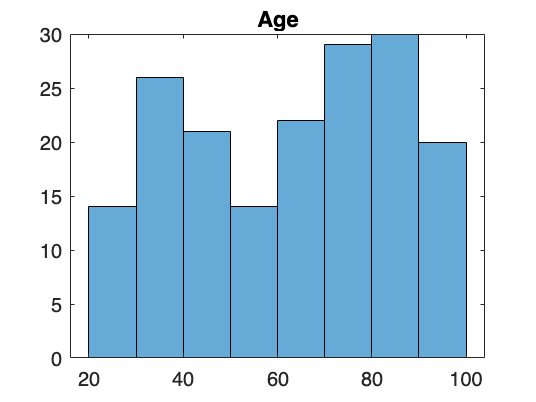

histogram(C1.Age)
title('Age')

mean(C1.Age)

ans = 61.9716


summary(C1(:,"Job"))

Variables:

    Job: 176×1 categorical

        Values:

            1       19   
            2      113   
            3        2   
            4        7   
            5       35   



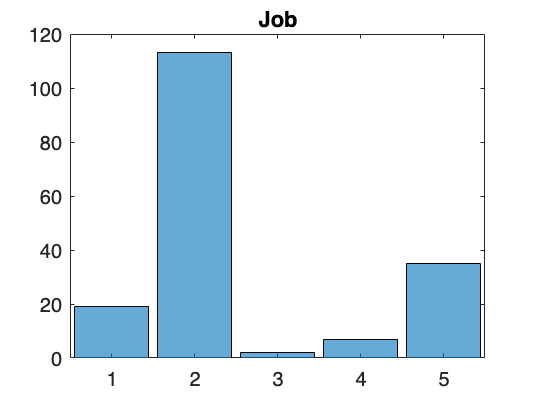

histogram(C1.Job)
title('Job')


summary(C1(:,"CitySize"))

Variables:

    CitySize: 176×1 categorical

        Values:

            1       66   
            2       72   
            3       38   



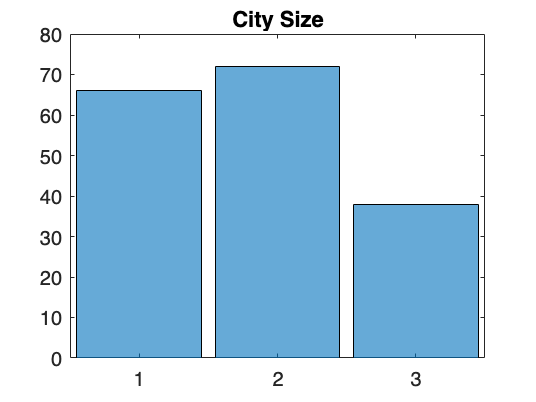

histogram(C1.CitySize)
title('City Size')



summary(C1(:,"Area"))

Variables:

    Area: 176×1 categorical

        Values:

            1      125   
            2       26   
            3       25   



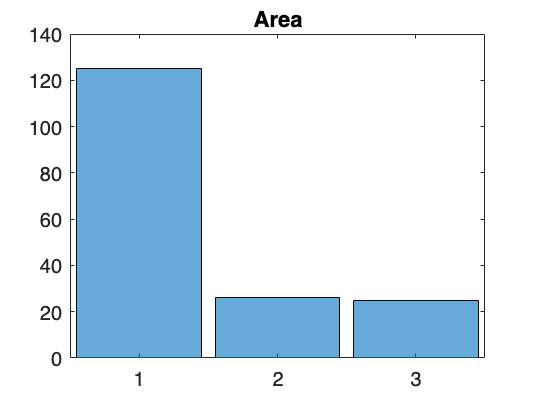

histogram(C1.Area)
title('Area')


summary(C1(:,"Investments"))

Variables:

    Investments: 176×1 categorical

        Values:

            1       52   
            2       54   
            3       70   



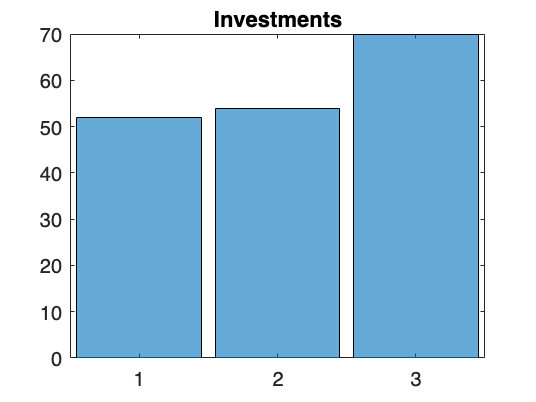

histogram(C1.Investments)
title(['Investments'])





summary(C1(:, "Income"))
histogram(C1.Income)
mean(C1.Income)

summary(C1(:, "Wealth"))
histogram(C1.Wealth)
mean(C1.Wealth)

summary(C1(:, "Debt"))
histogram(C1.Debt)
mean(C1.Debt)

summary(C1(:, "FinEdu"))
histogram(C1.FinEdu)
mean(C1.FinEdu)

summary(C1(:, "ESG"))
histogram(C1.ESG)
mean(C1.ESG)

summary(C1(:, "Digital"))
histogram(C1.Digital)
mean(C1.Digital)

summary(C1(:, "BankFriend"))
histogram(C1.BankFriend)
mean(C1.BankFriend)

summary(C1(:, "LifeStyle"))
histogram(C1.LifeStyle)
mean(C1.LifeStyle)

summary(C1(:, "Luxury"))
histogram(C1.Luxury)
mean(C1.Luxury)

summary(C1(:, "Saving"))
histogram(C1.Saving)
mean(C1.Saving)


C2 = dati(T6==2,:);

% Frequency tables
tabulate(C2.Job)

  Value    Count   Percent
      1       38     17.35%
      2      130     59.36%
      3        9      4.11%
      4        2      0.91%
      5       40     18.26%


tabulate(C2.Area)

  Value    Count   Percent
      1      158     72.15%
      2       40     18.26%
      3       21      9.59%


tabulate(C2.CitySize)

  Value    Count   Percent
      1       71     32.42%
      2       91     41.55%
      3       57     26.03%


tabulate(C2.Investments)

  Value    Count   Percent
      1       65     29.68%
      2       62     28.31%
      3       92     42.01%



summary(C2(:,"Age"))

Variables:

    Age: 219×1 double

        Values:

            Min          21   
            Median       64   
            Max          95   



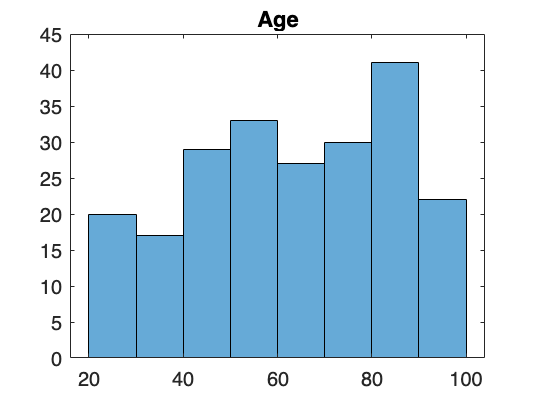

histogram(C2.Age)
title('Age')

mean(C2.Age)

ans = 62.5936


summary(C2(:,"Job"))

Variables:

    Job: 219×1 categorical

        Values:

            1       38   
            2      130   
            3        9   
            4        2   
            5       40   



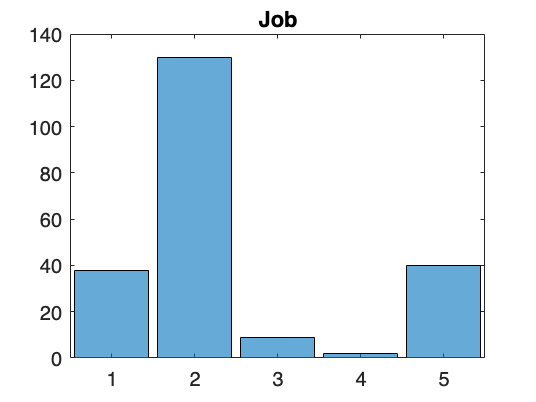

histogram(C2.Job)
title('Job')


summary(C2(:,"CitySize"))

Variables:

    CitySize: 219×1 categorical

        Values:

            1       71   
            2       91   
            3       57   



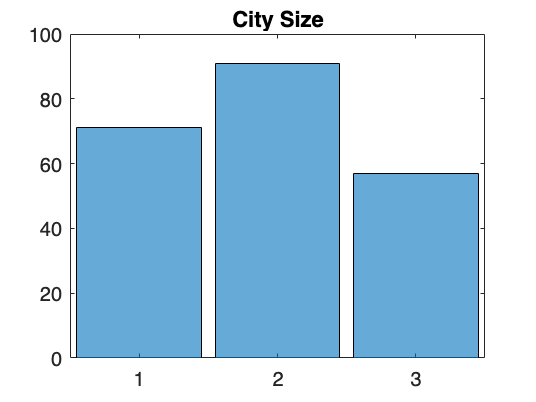

histogram(C2.CitySize)
title('City Size')



summary(C2(:,"Area"))

Variables:

    Area: 219×1 categorical

        Values:

            1      158   
            2       40   
            3       21   



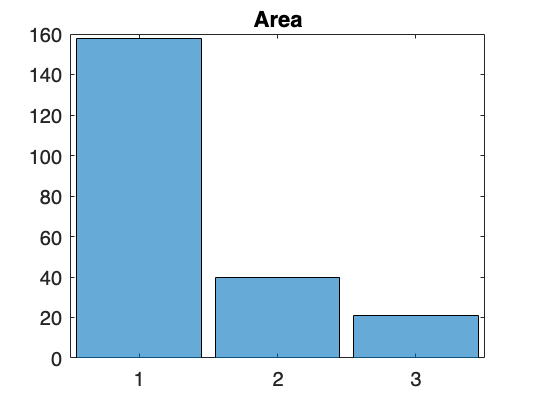

histogram(C2.Area)
title('Area')


summary(C2(:,"Investments"))

Variables:

    Investments: 219×1 categorical

        Values:

            1       65   
            2       62   
            3       92   



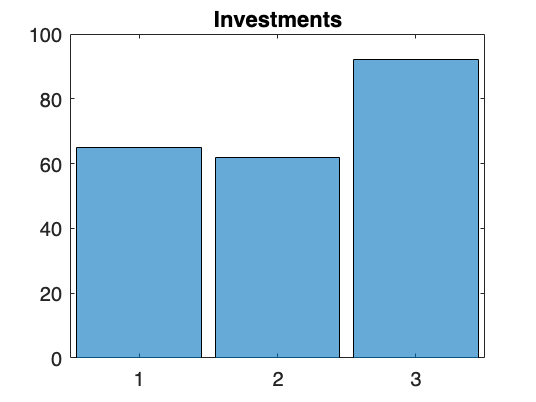

histogram(C2.Investments)
title(['Investments'])



summary(C2(:, "Income"))

Variables:

    Income: 219×1 double

        Values:

            Min             0 
            Median    0.55751 
            Max       0.96832 



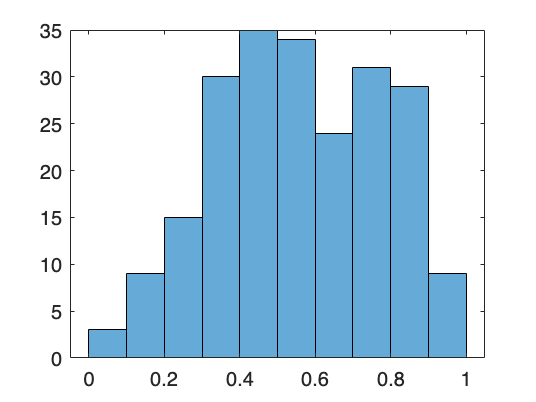

histogram(C2.Income)

mean(C2.Income)

ans = 0.5585


summary(C2(:, "Wealth"))

Variables:

    Wealth: 219×1 double

        Values:

            Min             0 
            Median    0.57065 
            Max       0.98524 



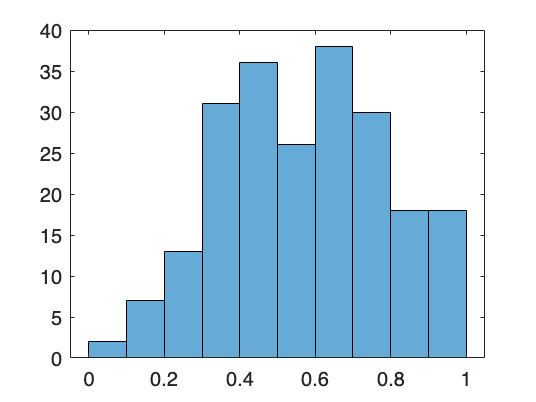

histogram(C2.Wealth)

mean(C2.Wealth)

ans = 0.5750


summary(C2(:, "Debt"))

Variables:

    Debt: 219×1 double

        Values:

            Min             0 
            Median    0.43717 
            Max       0.92213 



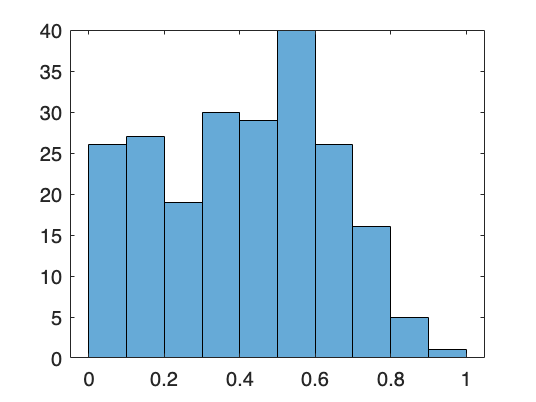

histogram(C2.Debt)

mean(C2.Debt)

ans = 0.4058


summary(C2(:, "FinEdu"))

Variables:

    FinEdu: 219×1 double

        Values:

            Min       0.12396 
            Median     0.5038 
            Max        0.9494 



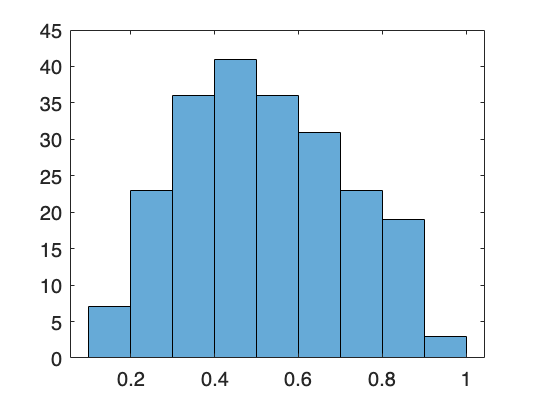

histogram(C2.FinEdu)

mean(C2.FinEdu)

ans = 0.5219


summary(C2(:, "ESG"))

Variables:

    ESG: 219×1 double

        Values:

            Min       0.13347 
            Median    0.59848 
            Max       0.95059 



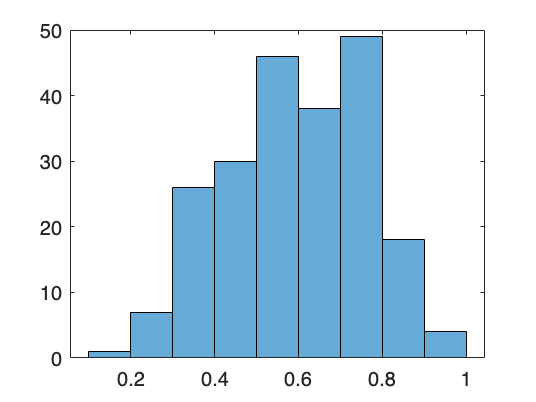

histogram(C2.ESG)

mean(C2.ESG)

ans = 0.5923


summary(C2(:, "Digital"))

Variables:

    Digital: 219×1 double

        Values:

            Min             0 
            Median    0.50917 
            Max        0.9684 



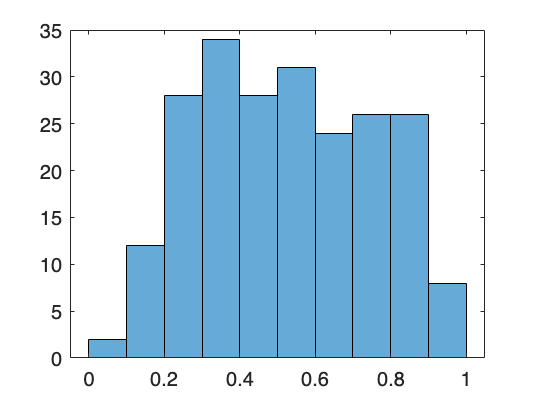

histogram(C2.Digital)

mean(C2.Digital)

ans = 0.5251


summary(C2(:, "BankFriend"))

Variables:

    BankFriend: 219×1 double

        Values:

            Min       0.16125 
            Median     0.6326 
            Max       0.93317 



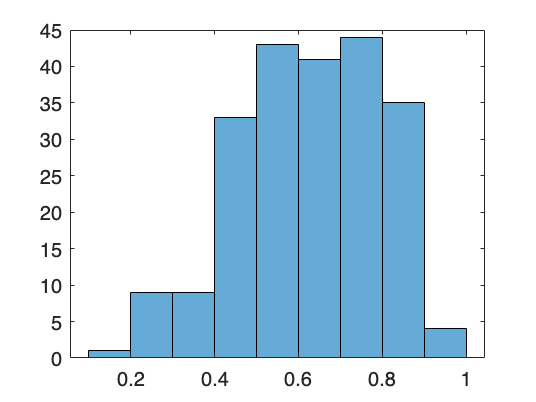

histogram(C2.BankFriend)

mean(C2.BankFriend)

ans = 0.6278


summary(C2(:, "LifeStyle"))

Variables:

    LifeStyle: 219×1 double

        Values:

            Min       0.084057
            Median     0.41589
            Max        0.94585



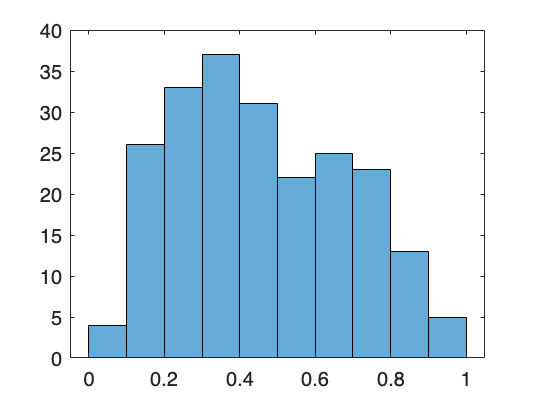

histogram(C2.LifeStyle)

mean(C2.LifeStyle)

ans = 0.4588


summary(C2(:, "Luxury"))

Variables:

    Luxury: 219×1 double

        Values:

            Min             0 
            Median     0.4654 
            Max       0.95601 



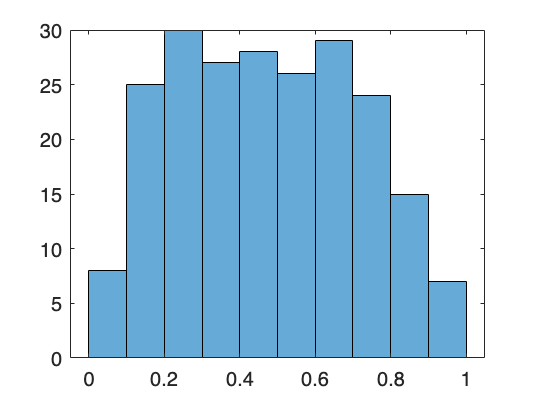

histogram(C2.Luxury)

mean(C2.Luxury)

ans = 0.4777


summary(C2(:, "Saving"))

Variables:

    Saving: 219×1 double

        Values:

            Min       0.040629
            Median     0.50143
            Max        0.89607



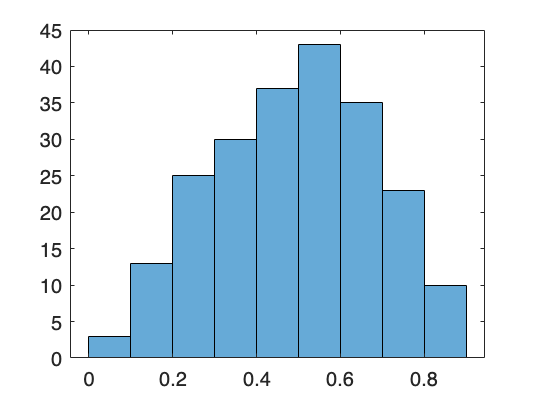

histogram(C2.Saving)

mean(C2.Saving)

ans = 0.4900

C3 = dati(T6==4,:);

% Frequency tables
tabulate(C3.Job)

  Value    Count   Percent
      1       74     11.90%
      2      427     68.65%
      3       10      1.61%
      4       16      2.57%
      5       95     15.27%


tabulate(C3.Area)

  Value    Count   Percent
      1      455     73.15%
      2      117     18.81%
      3       50      8.04%


tabulate(C3.CitySize)

  Value    Count   Percent
      1      230     36.98%
      2      256     41.16%
      3      136     21.86%


tabulate(C3.Investments)

  Value    Count   Percent
      1      158     25.40%
      2      180     28.94%
      3      284     45.66%



summary(C3(:,"Age"))

Variables:

    Age: 622×1 double

        Values:

            Min          19   
            Median       60   
            Max          95   



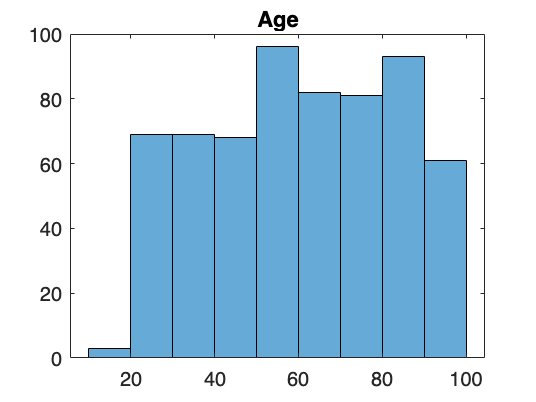

histogram(C3.Age)
title('Age')

mean(C3.Age)

ans = 60.1254


summary(C3(:,"Job"))

Variables:

    Job: 622×1 categorical

        Values:

            1       74   
            2      427   
            3       10   
            4       16   
            5       95   



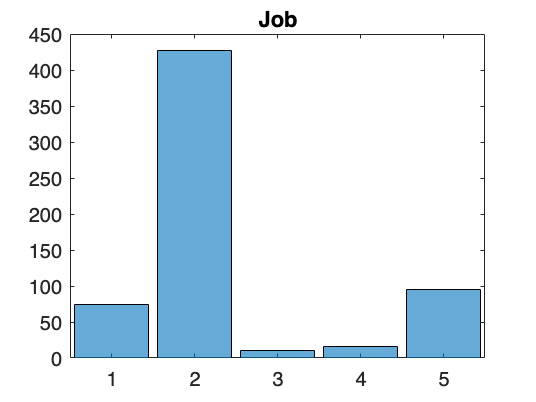

histogram(C3.Job)
title('Job')


summary(C3(:,"CitySize"))

Variables:

    CitySize: 622×1 categorical

        Values:

            1      230   
            2      256   
            3      136   



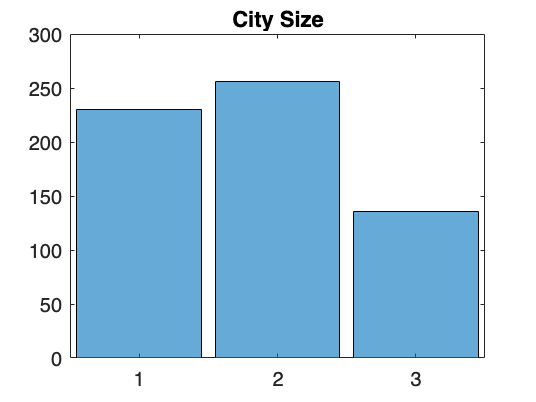

histogram(C3.CitySize)
title('City Size')



summary(C3(:,"Area"))

Variables:

    Area: 622×1 categorical

        Values:

            1      455   
            2      117   
            3       50   



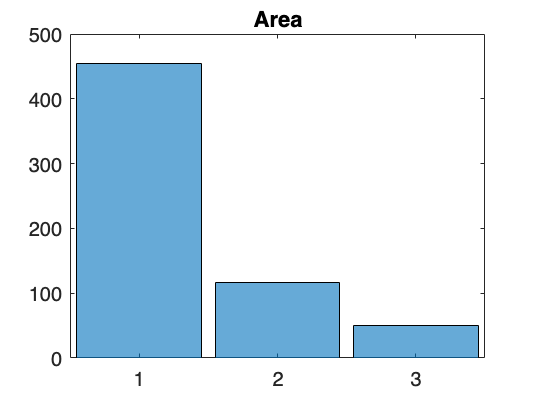

histogram(C3.Area)
title('Area')


summary(C3(:,"Investments"))

Variables:

    Investments: 622×1 categorical

        Values:

            1      158   
            2      180   
            3      284   



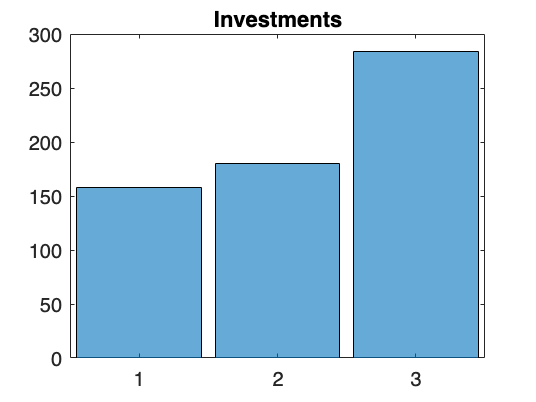

histogram(C3.Investments)
title(['Investments'])


summary(C3(:, "Income"))
histogram(C3.Income)
mean(C3.Income)

summary(C3(:, "Wealth"))
histogram(C3.Wealth)
mean(C3.Wealth)

summary(C3(:, "Debt"))
histogram(C3.Debt)
mean(C3.Debt)

summary(C3(:, "FinEdu"))
histogram(C3.FinEdu)
mean(C3.FinEdu)

summary(C3(:, "ESG"))
histogram(C3.ESG)
mean(C3.ESG)

summary(C3(:, "Digital"))
histogram(C3.Digital)
mean(C3.Digital)

summary(C3(:, "BankFriend"))
histogram(C3.BankFriend)
mean(C3.BankFriend)

summary(C3(:, "LifeStyle"))
histogram(C3.LifeStyle)
mean(C3.LifeStyle)

summary(C3(:, "Luxury"))
histogram(C3.Luxury)
mean(C3.Luxury)

summary(C3(:, "Saving"))
histogram(C3.Saving)
mean(C3.Saving)

C4 = dati(T6==4,:);

% Frequency tables
tabulate(C4.Job)

  Value    Count   Percent
      1       74     11.90%
      2      427     68.65%
      3       10      1.61%
      4       16      2.57%
      5       95     15.27%


tabulate(C4.Area)

  Value    Count   Percent
      1      455     73.15%
      2      117     18.81%
      3       50      8.04%


tabulate(C4.CitySize)

  Value    Count   Percent
      1      230     36.98%
      2      256     41.16%
      3      136     21.86%


tabulate(C4.Investments)

  Value    Count   Percent
      1      158     25.40%
      2      180     28.94%
      3      284     45.66%



summary(C4(:,"Age"))

Variables:

    Age: 622×1 double

        Values:

            Min          19   
            Median       60   
            Max          95   



histogram(C4.Age)
title('Age')

mean(C4.Age)

ans = 60.1254


summary(C4(:,"Job"))

Variables:

    Job: 622×1 categorical

        Values:

            1       74   
            2      427   
            3       10   
            4       16   
            5       95   



histogram(C4.Job)
title('Job')


summary(C4(:,"CitySize"))

Variables:

    CitySize: 622×1 categorical

        Values:

            1      230   
            2      256   
            3      136   



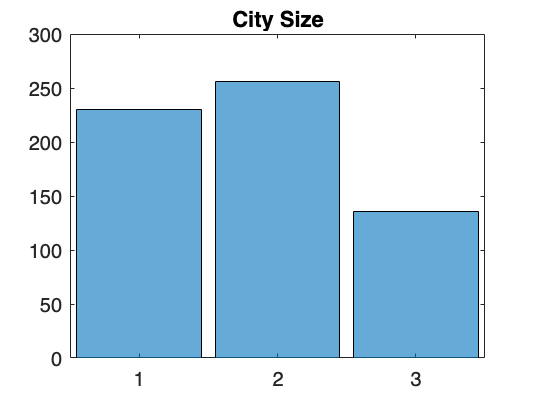

histogram(C4.CitySize)
title('City Size')



summary(C4(:,"Area"))

Variables:

    Area: 622×1 categorical

        Values:

            1      455   
            2      117   
            3       50   



histogram(C4.Area)
title('Area')


summary(C4(:,"Investments"))

Variables:

    Investments: 622×1 categorical

        Values:

            1      158   
            2      180   
            3      284   



histogram(C4.Investments)
title(['Investments'])


summary(C4(:, "Income"))
histogram(C4.Income)
mean(C4.Income)

summary(C4(:, "Wealth"))
histogram(C4.Wealth)
mean(C4.Wealth)

summary(C4(:, "Debt"))
histogram(C4.Debt)
mean(C4.Debt)

summary(C4(:, "FinEdu"))
histogram(C4.FinEdu)
mean(C4.FinEdu)

summary(C4(:, "ESG"))
histogram(C4.ESG)
mean(C4.ESG)

summary(C4(:, "Digital"))
histogram(C4.Digital)
mean(C4.Digital)

summary(C4(:, "BankFriend"))
histogram(C4.BankFriend)
mean(C4.BankFriend)

summary(C4(:, "LifeStyle"))
histogram(C4.LifeStyle)
mean(C4.LifeStyle)

summary(C4(:, "Luxury"))
histogram(C4.Luxury)
mean(C4.Luxury)

summary(C4(:, "Saving"))
histogram(C4.Saving)
mean(C4.Saving)


C5 = dati(T6==5,:);

% Frequency tables
tabulate(C5.Job)

  Value    Count   Percent
      1       84     11.37%
      2      476     64.41%
      3       22      2.98%
      4       12      1.62%
      5      145     19.62%


tabulate(C5.Area)

  Value    Count   Percent
      1      541     73.21%
      2      115     15.56%
      3       83     11.23%


tabulate(C5.CitySize)

  Value    Count   Percent
      1      243     32.88%
      2      300     40.60%
      3      196     26.52%


tabulate(C5.Investments)

  Value    Count   Percent
      1      203     27.47%
      2      221     29.91%
      3      315     42.63%



summary(C5(:,"Age"))

Variables:

    Age: 739×1 double

        Values:

            Min          19   
            Median       60   
            Max          95   



histogram(C5.Age)
title('Age')
mean(C5.Age)

ans = 60.5913


summary(C5(:,"Job"))

Variables:

    Job: 739×1 categorical

        Values:

            1       84   
            2      476   
            3       22   
            4       12   
            5      145   



histogram(C5.Job)
title('Job')

summary(C5(:,"CitySize"))

Variables:

    CitySize: 739×1 categorical

        Values:

            1      243   
            2      300   
            3      196   



histogram(C5.CitySize)
title('City Size')


summary(C5(:,"Area"))

Variables:

    Area: 739×1 categorical

        Values:

            1      541   
            2      115   
            3       83   



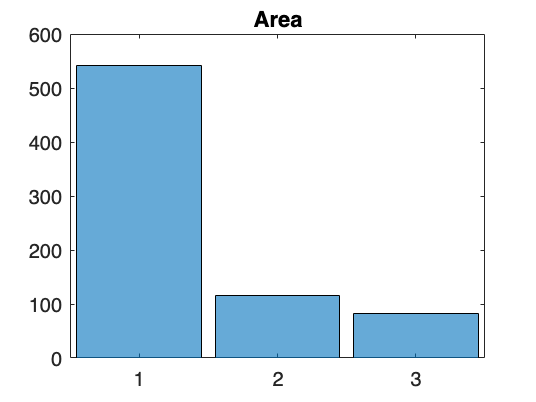

histogram(C5.Area)
title('Area')


summary(C5(:,"Investments"))

Variables:

    Investments: 739×1 categorical

        Values:

            1      203   
            2      221   
            3      315   



histogram(C5.Investments)
title(['Investments'])


summary(C5(:, "Income"))
histogram(C5.Income)
mean(C5.Income)

summary(C5(:, "Wealth"))
histogram(C5.Wealth)
mean(C5.Wealth)

summary(C5(:, "Debt"))
histogram(C5.Debt)
mean(C5.Debt)

summary(C5(:, "FinEdu"))
histogram(C5.FinEdu)
mean(C5.FinEdu)

summary(C5(:, "ESG"))
histogram(C5.ESG)
mean(C5.ESG)

summary(C5(:, "Digital"))
histogram(C5.Digital)
mean(C5.Digital)

summary(C5(:, "BankFriend"))
histogram(C5.BankFriend)
mean(C5.BankFriend)

summary(C5(:, "LifeStyle"))
histogram(C5.LifeStyle)
mean(C5.LifeStyle)

summary(C5(:, "Luxury"))
histogram(C5.Luxury)
mean(C5.Luxury)

summary(C5(:, "Saving"))
histogram(C5.Saving)
mean(C5.Saving)


C6 = dati(T6==6,:);

% Frequency tables
tabulate(C6.Job)

  Value    Count   Percent
      1        8      8.60%
      2       57     61.29%
      3        3      3.23%
      4        2      2.15%
      5       23     24.73%


tabulate(C6.Area)

  Value    Count   Percent
      1       69     74.19%
      2       14     15.05%
      3       10     10.75%


tabulate(C6.CitySize)

  Value    Count   Percent
      1       31     33.33%
      2       33     35.48%
      3       29     31.18%


tabulate(C6.Investments)

  Value    Count   Percent
      1       23     24.73%
      2       38     40.86%
      3       32     34.41%



summary(C6(:,"Age"))

Variables:

    Age: 93×1 double

        Values:

            Min          19   
            Median       59   
            Max          95   



histogram(C6.Age)
title('Age')

mean(C6.Age)

ans = 58.6667


summary(C6(:,"Job"))

Variables:

    Job: 93×1 categorical

        Values:

            1        8   
            2       57   
            3        3   
            4        2   
            5       23   



histogram(C6.Job)
title('Job')


summary(C6(:,"CitySize"))

Variables:

    CitySize: 93×1 categorical

        Values:

            1       31   
            2       33   
            3       29   



histogram(C6.CitySize)
title('City Size')



summary(C6(:,"Area"))

Variables:

    Area: 93×1 categorical

        Values:

            1       69   
            2       14   
            3       10   



histogram(C6.Area)
title('Area')


summary(C6(:,"Investments"))

Variables:

    Investments: 93×1 categorical

        Values:

            1       23   
            2       38   
            3       32   



histogram(C6.Investments)
title(['Investments'])



summary(C6(:, "Income"))
histogram(C6.Income)
mean(C6.Income)

summary(C6(:, "Wealth"))
histogram(C6.Wealth)
mean(C6.Wealth)

summary(C6(:, "Debt"))
histogram(C6.Debt)
mean(C6.Debt)

summary(C6(:, "FinEdu"))
histogram(C6.FinEdu)
mean(C6.FinEdu)

summary(C6(:, "ESG"))
histogram(C6.ESG)
mean(C6.ESG)

summary(C6(:, "Digital"))
histogram(C6.Digital)
mean(C6.Digital)

summary(C6(:, "BankFriend"))
histogram(C6.BankFriend)
mean(C6.BankFriend)

summary(C6(:, "LifeStyle"))
histogram(C6.LifeStyle)
mean(C6.LifeStyle)

summary(C6(:, "Luxury"))
histogram(C6.Luxury)
mean(C6.Luxury)

summary(C6(:, "Saving"))
histogram(C6.Saving)
mean(C6.Saving)




% next step tirare fuori l'indice dei 6 negli ultimi due cluster
% provare ad escluderli e rivedere come clusterizza il resto dei dati

%PARTE 2 scelta prodotto %NO

path = '/Users/veronicalucchetti/Desktop/TESI/Products.mat';

load(path)

Error using load
Unable to find file or directory '/Users/veronicalucchetti/Desktop/TESI/Products.mat'.

% creo matrice needs of each cluster %era un mio tentativo fallito
%NO
rows = 6;
cols = 8;
needcluster = zeros(rows, cols);
for i = 1:rows
    C6 = dati(T6==i,:)
   
needcluster(i, 1) = mean(C6.Age)
needcluster(i,2)=mean(C6.Income)
needcluster(i,3)=mean(C6.Wealth)
needcluster(i,4)=mean(C6.Debt)
needcluster(i,5)=mean(C6.FinEdu)
needcluster(i,6)=mean(C6.Saving)
needcluster(i,7)=0.2*needcluster(i,2) + 0.2*needcluster(i,6) + 0.1*needcluster(i,3) + 0.3*needcluster(i,5) + 0.2*(-needcluster(i,4))

end
needcluster(1,8)=3
needcluster(2,8)=3
needcluster(3,8)=3
needcluster(4,8)=3
needcluster(5,8)=3
needcluster(6,8)=2

%risk propensity index
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)


%NO %idem tentativo fallito

% Define the Excel file path
excel_file = '/Users/veronicalucchetti/Desktop/TESI/Needs1.xlsx';

% Read the data from the Excel file
needs = xlsread(excel_file);

% Define the MAT file name
needs_file = 'needs.mat';

% Save the data into a MAT file
save(needs_file, 'needs');



## Next Best Action: recommending products

Now we generate the personalized recommendation for the Accumulation products, that is, Products.Type==1.

I adopt the following rules, for each client:

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting one single product** - alternatively we might suggest **a list of products**, ranked based on their fit to each client profile (the first approach, being "straight", would be preferable for a robo-advisory service or a sales network that needs a lot of support, the latter is more suitable for a network of expert financial consultants who just need a little decision support).

For simplicity and to continue the example, we do that for the clients in the test set (but the rules work for an arbitrary set of clients).

### Retrieving data

Retrieving IDs and risk propensities for the client in the test set, and products (using the variable idxPermutation).

% Define the Excel file path 
excel_file = 'Products.xlsx';

% Read the data from the Excel file into a table
%Products = readtable(excel_file);

% Read the data from the Excel file
Products = xlsread(excel_file);

% Define the MAT file name
Products_file = 'Products.mat';

% Save the data into a MAT file
save(Products_file, 'Products');

% Read the data from the Excel file into a table
Products = readtable(excel_file);



%ACCUMULATION CLIENTS %I WAS ONLY TRYING ON SMALL DATA SET BUT IS USELESS
% Retrieving clients IDs
ClientID = needs.ID

TargetClientID = ClientID(needs.Investment==3); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
ClientRiskProp= needs.RiskProp
TargetClientRiskPropensity = ClientRiskProp(needs.Investment==3); 

% Let's have a look at these incomes...
figure
histogram(TargetClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')

AccumulationProducts = Products(Products.Type == 1,:)

Dot indexing is not supported for variables of this type.

### Creating the personalized recommandations:

- The suitable products are those with a risk level below the client risk tolerance;

- Among those products, we select the one with the highest risk level (sure, we might do otherwise, it depends on the situation).

NBA_IDProduct = [];
RecommendedRiskLevel = [];
minRisk = min(AccumulationProducts.Risk);

for i = 1: size(TargetClientRiskPropensity, 1)
    if TargetClientRiskPropensity(i)> minRisk
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<TargetClientRiskPropensity(i)));
        NBA_IDProduct = [NBA_IDProduct; AccumulationProducts.ID(AccumulationProducts.Risk == M)];
    else
        % no suitable product in the product range
        NBA_IDProduct = [NBA_IDProduct; '0'];
        M = 0;
    end
    RecommendedRiskLevel = [RecommendedRiskLevel; M];
end

% recommendations
CatID = categorical(TargetClientID);
NBA = [CatID NBA_IDProduct];

figure
c = linspace(0,1,length(TargetClientRiskPropensity));
scatter(TargetClientRiskPropensity, RecommendedRiskLevel, [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')

%Income CLIENTS SAME I WAS TRYING ON SMALL DATASET
% Retrieving clients IDs

IncomeClientID = ClientID(needs.Investment==2); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
ClientRiskProp= needs.RiskProp
IncomeClientRiskPropensity = ClientRiskProp(needs.Investment==2); 

% Let's have a look at these incomes...
figure
histogram(IncomeClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')

IncomeProducts = Products(Products.Type == 0,:)

IP_IDProduct = [];
RecommendedRiskLevelIP = [];
minRiskINC = min(IncomeProducts.Risk);

for i = 1: size(IncomeClientRiskPropensity, 1)
    if IncomeClientRiskPropensity(i)> minRiskINC
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<IncomeClientRiskPropensity(i)));
        IP_IDProduct = [IP_IDProduct; IncomeProducts.ID(IncomeProducts.Risk == M)];
    else
        % no suitable product in the product range
        IP_IDProduct = [IP_IDProduct; '0'];
        M = 0;
    end
    RecommendedRiskLevelIP = [RecommendedRiskLevelIP; M];
end

% recommendations
CatID = categorical(TargetClientID);
NBA_IP = [CatID IP_IDProduct];


%PROVO A CALCOLARE IL PRODOTTO PER TUTTI I CLIENTI
% DA QUI REAL ONE

%ACCUMULATION CLIENTS
% Retrieving clients IDs
ClientID_full = BankClients.ID
category3=categorical({'3'})
TargetClientID_full = ClientID_full(BankClients.Investments==category3); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
ClientRiskProp_full=0.2*BankClients.Income+0.2*BankClients.Saving+0.1*BankClients.Wealth+0.2*BankClients.FinEdu+0.1*(BankClients.Age/100)+0.2*(1/BankClients.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

TargetClientRiskPropensity_full = ClientRiskProp_full(BankClients.Investments==category3); 

% Let's have a look at these incomes...
figure
histogram(TargetClientRiskPropensity_full, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


AccumulationProducts = Products(Products.Type == 1,:)

NBA_ACProduct_full = [];
RecommendedRiskLevel_full = [];
minRisk_full = min(AccumulationProducts.Risk);

for i = 1: size(TargetClientRiskPropensity_full, 1)
    if TargetClientRiskPropensity_full(i)> minRisk_full
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<TargetClientRiskPropensity_full(i)));
        NBA_ACProduct_full = [NBA_ACProduct_full; AccumulationProducts.ID(AccumulationProducts.Risk == M)];
    else
        % no suitable product in the product range
        NBA_ACProduct_full = [NBA_ACProduct_full; '0'];
        M = 0;
    end
    RecommendedRiskLevel_full = [RecommendedRiskLevel_full; M];
end

% recommendations
CatID_full = categorical(TargetClientID_full);
NBA_full = [CatID_full NBA_ACProduct_full];

figure
c = linspace(0,1,length(TargetClientRiskPropensity_full));
scatter(TargetClientRiskPropensity_full, RecommendedRiskLevel_full, [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')



%SAME BUT FOR THE ONES WITH INCOME INVESTMENTS

% Retrieving clients IDs
IncomeClientID_full = BankClients.ID
category2=categorical({'2'})
IncomeClientID_full = IncomeClientID_full(BankClients.Investments==category2); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
IncomeClientRiskProp_full=0.2*BankClients.Income+0.2*BankClients.Saving+0.1*BankClients.Wealth+0.2*BankClients.FinEdu+0.1*(BankClients.Age/100)+0.2*(1/BankClients.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

IncomeClientRiskPropensity_full = IncomeClientRiskProp_full(BankClients.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(IncomeClientRiskPropensity_full, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


IncomeProducts = Products(Products.Type == 0,:)

NBA_IProduct_full = [];
RecommendedRiskLevelIN_full = [];
minRiskIN_full = min(IncomeProducts.Risk);

for i = 1: size(IncomeClientRiskPropensity_full, 1)
    if IncomeClientRiskPropensity_full(i)> minRiskIN_full
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<IncomeClientRiskPropensity_full(i)));
        NBA_IProduct_full = [NBA_IProduct_full; IncomeProducts.ID(IncomeProducts.Risk == M)];
    else
        % no suitable product in the product range
        NBA_IProduct_full = [NBA_IProduct_full; '0'];
        M = 0;
    end
    RecommendedRiskLevelIN_full = [RecommendedRiskLevelIN_full; M];
end

% recommendations
IncomeCatID_full = categorical(IncomeClientID_full);
NBAIncome_full = [IncomeCatID_full NBA_IProduct_full];

figure
c = linspace(0,1,length(IncomeClientRiskPropensity_full));
scatter(IncomeClientRiskPropensity_full, RecommendedRiskLevelIN_full, [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')

%SAME BUT ONLY FOR EACH CLUSTER CLIENTS


%CLUSTER 1 ACCUMULATION

ClientID_C1 = C1.ID

ClientID_C1 = 176×1 categorical array
     3 
     19 
     25 
     26 
     35 
     37 
     41 
     58 
     115 
     130 
     131 
     138 
     165 
     193 
     199 
     205 
     208 
     219 
     243 
     251 
     256 
     262 
     271 
     296 
     298 
     301 
     310 
     316 
     322 
     333 



category3=categorical({'3'})

category3 = categorical
     3 


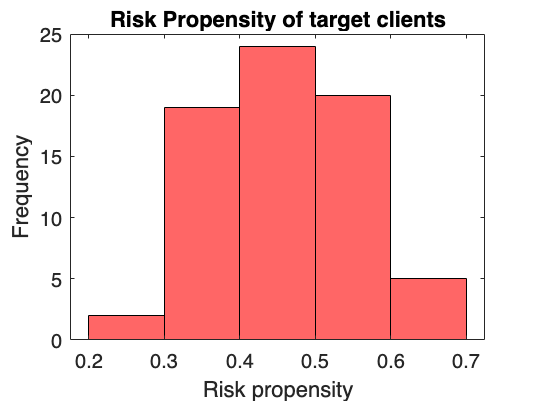

C1ClientID = ClientID_C1(C1.Investments==category3); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
C1RiskProp_full=0.2*C1.Income+0.2*C1.Saving+0.1*C1.Wealth+0.2*C1.FinEdu+0.1*(C1.Age/100)+0.2*(1/C1.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

C1ClientRiskPropensity = C1RiskProp_full(C1.Investments==category3); 

% Let's have a look at these incomes...
figure
histogram(C1ClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')



AccumulationProducts = Products(Products.Type == 1,:)

AccumulationProducts = 7×3 table
    ID    Type    Risk
    __    ____    ____

    1      1      0.55
    5      1      0.41
    6      1      0.36
    7      1      0.75
    8      1      0.48
    9      1      0.27
    11     1      0.88



NBA_C1P = [];
NBA_C1Product= double(NBA_C1P);
RecommendedRiskLevel_C1 = [];
minRisk_C1 = min(AccumulationProducts.Risk);

for i = 1: size(C1ClientRiskPropensity, 1)
    if C1ClientRiskPropensity(i)> minRisk_C1
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C1ClientRiskPropensity(i)));
        NBA_C1P= [NBA_C1P; AccumulationProducts.ID(AccumulationProducts.Risk == M)];
    else
        % no suitable product in the product range
        NBA_C1P= [NBA_C1P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C1 = [RecommendedRiskLevel_C1; M];
end

% recommendations
CatID_C1 = categorical(C1ClientID);
NBA_C1= [CatID_C1 NBA_C1P];


histogram(NBA_C1P, 'FaceColor', 'lb')

Error using histogram
Error setting property 'FaceColor' of class 'Histogram':
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white', and 'none'. Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.

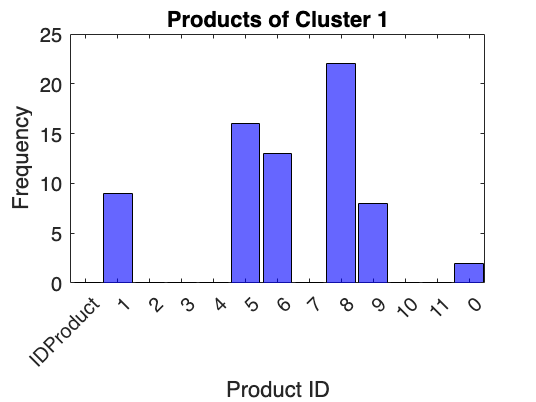

title('Products of Cluster 1')
xlabel('Product ID')
ylabel('Frequency')

%fare same per income e poi per gli altri cluster



%DA QUI IN POI E' LA PARTE DELL'ALGORITMO PREDITTIVO CHE NON SO BENE A COSA SERVA

### Dividing our data

For the sake of time scarcity/brevity (...here we are doing an exercise, and I'm just giving you a hint of a solution), I'll go for the first approach, but whwnever is possible I strongly suggest and practice the second approach.

I partion data directly, splitting features and responses, but you might find useful this function, `cvpartition`, that defines random partitions on a data set: [https://it.mathworks.com/help/stats/cvpartition.html](https://it.mathworks.com/help/stats/cvpartition.html).

% Create two new columns filled with zeros
newColumn1 = zeros(size(dati, 1), 1);
newColumn2 = zeros(size(dati, 1), 1);

% Assuming the categorical variable is stored in the first column of 'data'
categoricalVariable = dati.Investments;
%categoricalVariableNumeric = grp2idx(categoricalVariable);

% Update the new columns based on the values of the categorical variable

% If categorical variable is 1, set the corresponding entry in newColumn1 to 1
category2=categorical({'2'});
for i=1:size(dati,1)
    if categoricalVariable(i,1) == 2;
        newColumn1(i,1) = 1;
    end
end
% If categorical variable is 2, set the corresponding entry in newColumn2 to 1
newColumn2(categoricalVariable = 3) = 1;

% Add the new columns to the dataset
extendedData = [data newColumn1 newColumn2];


% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
% Removing the gender and the family size
%Data(:, "Gender") = [];
%Data(:, "FamilySize") = [];
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]
% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features
% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end)];% To use the dummy variables in a model, we must delete a column
end
X = [XCat XNum];% se voglio usare le dummy (colonna 14 no inv,
% colonna 15 e' lump sum, col16 e' capital
% accumulation)
dati = Data; % se voglio usare dataset originario
firstcolumns=BankClients(:,1:end);
lastcolumn1=zeros(5000,1);
lastcolumn2=zeros(5000,1);
dataset=firstcolumns;
dataset.IncomeInvestment=lastcolumn1;
dataset.AccumulationInvestment=lastcolumn2;
invest=BankClients.Investments;
categ2=categorical({'2'});
categ3=categorical({'3'});
dataset.IncomeInvestment(invest == categ2) =1;
dataset.AccumulationInvestment(invest == categ3) =1;



nObs = size(X, 1);
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
nObsTrain = round(0.75*nObs);

XTrain = X(1:nObsTrain,:);
XTest = X(nObsTrain+1:end,:);

yInvIncTrain = X(1:nObsTrain,15);
yInvIncTest = X(nObsTrain+1:end,15);

yInvAccTrain = X(1:nObsTrain,16);
yInvAccTest = X(nObsTrain+1:end,16);

varNames = {'Gen','Gen2','job','job1','job2','job3','job4','area','area1','area2','size','size1','size2','noinv','lumpsum','capacc','Age', 'familysize','Income', 'Wealth','debt','finedu','esg','digital','bankfrienly','lifestyle','luxury','saving'};
XTrainTable=table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7),XTrain(:,8),XTrain(:,9),XTrain(:,10),XTrain(:,11),XTrain(:,12),XTrain(:,13),XTrain(:,14),XTrain(:,15),XTrain(:,16),XTrain(:,17),XTrain(:,18),XTrain(:,19),XTrain(:,20),XTrain(:,21),XTrain(:,22),XTrain(:,23),XTrain(:,24),XTrain(:,25),XTrain(:,26),XTrain(:,27),XTrain(:,28), 'VariableNames',varNames);

### Using the classification learner

Most of the time you need quick results. So let's use the classification learner, speeding up the modeling process, as it (is not exceptional but) allows for rapid model training/validation, then it generates the code (see an example here: [https://it.mathworks.com/help/stats/code-generation-and-classification-learner-app.html).](https://it.mathworks.com/help/stats/code-generation-and-classification-learner-app.html).) If you need a tool for rapid prototyping, you might also try [https://www.dataiku.com/product/get-started/](https://www.dataiku.com/product/get-started/) (the free trial doesn't expire, and it's enough for doing some fast model/data understanding - it's especially good if you have a Mac).

**NOTE**: my suggestion is, when you are researching the model that will be best for the type of data use the fastest programming language or platform FOR YOU (R/SPSS, Matlab/Octave, Python, SAS, Stan, Julia, whatever you like/you are proficient in). If you want to build a large scale deployment of a learning algorithm, first do fast prototyping (incidentally Matlab is a great prototyping language). So you can sort of getting your learning algorithms working quickly. Only then spend your time re-implementing the algorithm in the production language. If you can get your learning algorithms to work more quickly in your preferred language, then you have huge overall time savings.

### Doing some feature engineering using domain knowledge

I try using some financial know-how to refine the process. It's ususally a very good idea, a key advantage.

In this case, following the financial advisory best practice, my idea is:

- accumulation investment products are mainly (though not only) intended for relatively young people, say workers, who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older (often they are retired);

- since the Y's derive from the behavior of financial advisors who hopefully follow this practice, an interesting variable is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture I try to eliminate family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important). Even risk propensity shouldn't be so important in order to estimate financial needs (it's important in order to choose the right risk level given the product).

*HINT*: try to engineer your features (maybe you can find a rationale for the number of family members, the gender, maybe it's linked to the client's life-cycle or whatever).%%

%%prova senza lognormale %non va
IncomeWealthRatio = zeros(nObs,1); 
IncomeWealthRatio(Data.Wealth) = log(Data.Income)./log(Data.Wealth);  
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinEdu) Income Wealth ];

xnames = {'IncomeWratio','Age', 'Financial Education', 'Income', 'Wealth'};
logWealth = log(Data.Wealth);%lognormal
logIncome = log(Data.Income);          
IncomeWealthRatio = zeros(nObs,1);    
IncomeWealthRatio(Data.Wealth>10) = logIncome(Data.Wealth>10)./logWealth(Data.Wealth>10);
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinEdu) logIncome logWealth ];

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), 'VariableNames',xnames);


### Directly training and testing an ensemble model

After a first, quick model assessment using the classification learner app, we are back...we are going to create a predictive classification ensemble using my selection of predictors.

Let's say we want to cross-validate an ensemble of classification trees using:

- Bootstrap Aggregation - basically a Random Forest (see [https://it.mathworks.com/matlabcentral/answers/92525-where-can-i-find-more-information-about-breiman-s-random-forest-method-used-by-treebagger-in-stati#answer_101875](https://it.mathworks.com/matlabcentral/answers/92525-where-can-i-find-more-information-about-breiman-s-random-forest-method-used-by-treebagger-in-stati#answer_101875)), which worked well in the classification learner app;

- 5-fold cross-validation;

- Each tree should be split a maximum of 5 times using a decision tree template.

rng(5); % For reproducibility
t = templateTree('MaxNumSplits',5);
MdlBagging = fitcensemble(XsmallTrainTable,yInvAccTrain,'Method','Bag','Learners',t,'KFold',5,'CrossVal','on');

Now we plot the cumulative misclassification rate, displaying the estimated generalization error of the ensemble. Plotting the cumulative loss allows you to monitor how the loss changes as weak learners accumulate in the ensemble.

CVLoss is the loss obtained by the cross-validated model (for every fold, `kfoldLoss` computes the loss).

CVLoss = kfoldLoss(MdlBagging,'Mode','cumulative');
figure;
plot(CVLoss);
ylabel('10-fold Misclassification rate');
xlabel('Learning cycle');
estGenError = CVLoss(end)


rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

[labels,scores] = predict(MdlOptimum,XsmallTest);

figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')


tp = sum((labels == '1') & (yInvAccTest=='1'));
fp = sum((labels == '1') & (yInvAccTest=='0'));
fn = sum((labels == '0') & (yInvAccTest=='1'));
prec = tp / (tp + fp)
rec = tp / (tp + fn)
F1 = 2 * prec * rec / (prec + rec)

## PROVA

% Retrieving clients IDs
ClientID_C1 = BankClients.ID(idxPermutation);
ClientIDTest = ClientID_C1(nObsTrain+1:end,:);
TargetClientID = ClientIDTest(labels=='1');

% Retrieving clients' risk propensities
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);
ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity = ClientRiskPropensityTest(labels=='1');

% Let's have a look at these risk propensities...
figure
histogram(ClientRiskPropensityTest, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')
IncomeProducts = Products(Products.Type == 1,:)